clc
clear
close all

bag1 = rosbag('/LAB3/curry_ss_2nd_floor.bag');
bagselect = select(bag1, 'Topic', '/imu');
msgStructs = readMessages(bagselect, 'DataFormat', 'struct');
disp(msgStructs{1}.MagField)

                MessageType: 'sensor_msgs/MagneticField'
                     Header: [1×1 struct]
             MagneticField_: [1×1 struct]
    MagneticFieldCovariance: [9×1 double]



qx = cellfun(@(m) double(m.Imus.Orientation.X),msgStructs);
qy = cellfun(@(m) double(m.Imus.Orientation.Y),msgStructs);
qz = cellfun(@(m) double(m.Imus.Orientation.Z),msgStructs);
qw = cellfun(@(m) double(m.Imus.Orientation.W),msgStructs);

accelx = cellfun(@(m) double(m.Imus.LinearAcceleration.X),msgStructs);
accely = cellfun(@(m) double(m.Imus.LinearAcceleration.Y),msgStructs);
accelz = cellfun(@(m) double(m.Imus.LinearAcceleration.Z),msgStructs);

gyrox = cellfun(@(m) double(m.Imus.AngularVelocity.X),msgStructs);
gyroy = cellfun(@(m) double(m.Imus.AngularVelocity.Y),msgStructs);
gyroz = cellfun(@(m) double(m.Imus.AngularVelocity.Z),msgStructs);

magx = .0001 * cellfun(@(m) double(m.MagField.MagneticField_.X),msgStructs);
magy = .0001 * cellfun(@(m) double(m.MagField.MagneticField_.Y),msgStructs);
magz = .0001 * cellfun(@(m) double(m.MagField.MagneticField_.Z),msgStructs);

times = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs);
timens = cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs);

L = length(msgStructs);

t = zeros(L,1);
eulers = zeros(L,3);
eulers_test = zeros(L,3);

for i = 1:L
    quat1 = [qw(i), qx(i), qy(i), qz(i)];
    eulers(i,:) = (180/pi)*(quat2eul(quat1));
    t(i) = times(i) + timens(i)/(10^(length(timens(i))));
end

for i = 1:L
    quat1 = [qw(i), qx(i), qy(i), qz(i)];
    eulers(i,:) = (180/pi)*(quat2eul(quat1));
    t(i) = times(i) + timens(i)*10^-9;
end

for i = 1:L 
    line = string(msgStructs{i}.FullVNYMRString);
    data1 = split(line, "*");
    data2 = split(data1(1), ",");

    if length(data2) ~= 13
%         disp(line)
%         disp(data1)
%         disp(data2)
        continue
    else
        eulers_test(i,1) = double(data2(2));
        eulers_test(i,2) = double(data2(3));
        eulers_test(i,3) = double(data2(4));
    end
end

t = t - t(1);
% t = linspace(0, L/40, L);
% t = t - t(1);

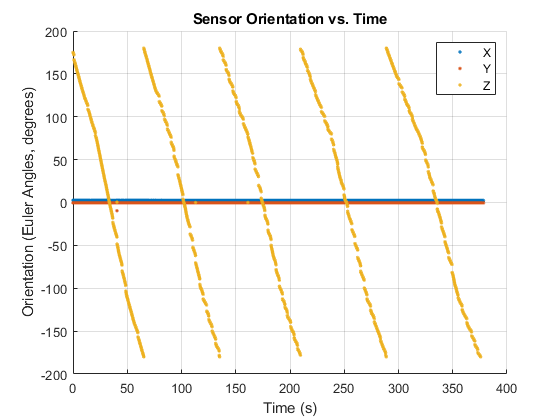

figure
hold on; grid on; plot(t, [eulers(:,3), eulers(:,2), eulers(:,1)], '.'); title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X', 'Y', 'Z'); set(gcf,'Visible','on'); hold off;

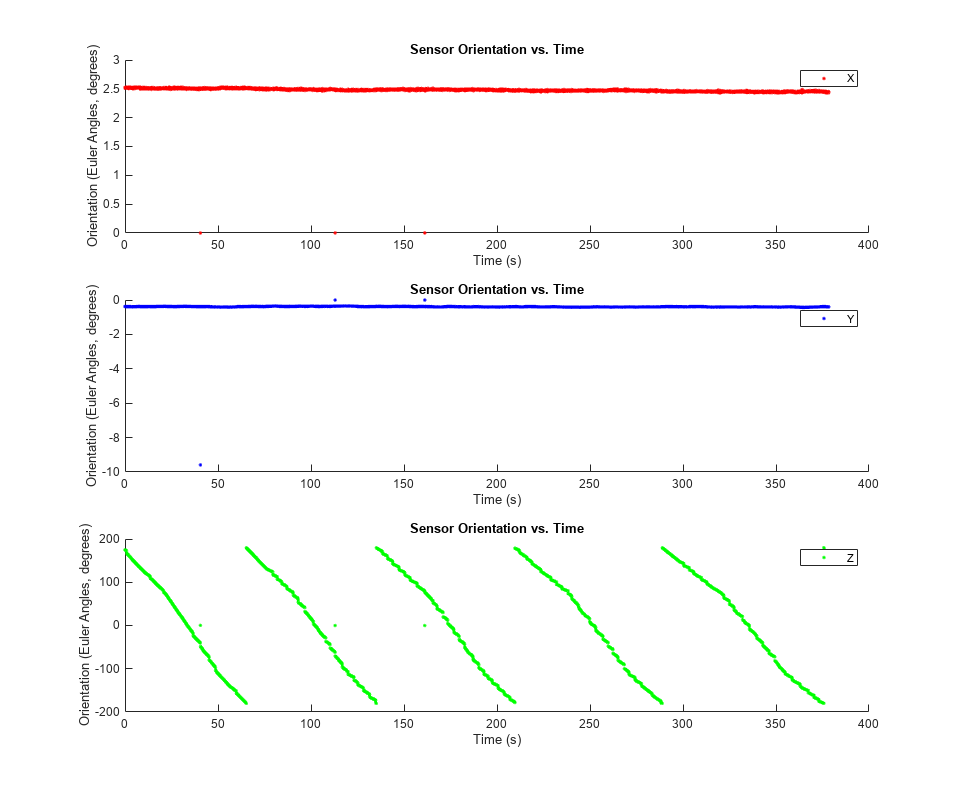


figure
set(gcf, 'position', [0, 0, 1800, 1500])
subplot(3,1,1); grid on; scatter(t, eulers(:,3), '.r'); title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X');

subplot(3,1,2); grid on; scatter(t, eulers(:,2), '.b'); title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Y');

subplot(3,1,3); grid on; scatter(t, eulers(:,1), '.g');  title('Sensor Orientation vs. Time');  
xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Z'); hold off;


% figure
% grid on; scatter(t, eulers(:,1), '.g');  title('Sensor Orientation vs. Time');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Z'); hold off;

% figure
% set(gcf, 'position', [0, 0, 1800, 1500])
% subplot(3,1,1); grid on; scatter(t, eulers_test(:,3), '.r'); title('RAW DATA');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('X');
% 
% subplot(3,1,2); grid on; scatter(t, eulers_test(:,2), '.b'); title('RAW DATA');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Y');
% 
% subplot(3,1,3); grid on; scatter(t, eulers_test(:,1), '.g');  title('RAW DATA');  
% xlabel('Time (s)'); ylabel('Orientation (Euler Angles, degrees)'); legend('Z'); set(gcf,'Visible','on'); hold off;

% figure
% set(gcf, 'position', [0, 0, 1800, 1500])
% subplot(3,1,1); grid on; scatter(t, magx, '.r'); title('Magnetic Field');  
% xlabel('Time (s)'); ylabel('Field (T)'); legend('X');
% 
% subplot(3,1,2); grid on; scatter(t, magy, '.b'); title('Magnetic Field');  
% xlabel('Time (s)'); ylabel('Field (T)'); legend('Y');
% 
% subplot(3,1,3); grid on; scatter(t, magz, '.g');  title('Magnetic Field');  
% xlabel('Time (s)'); ylabel('Field (T)'); legend('Z'); set(gcf,'Visible','on'); hold off;

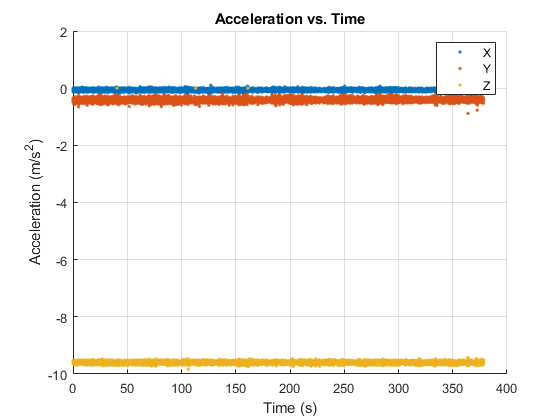

figure
hold on; grid on; scatter(t, [accelx, accely, accelz], '.'); title('Acceleration vs. Time');  
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)'); legend('X', 'Y', 'Z'); set(gcf,'Visible','on'); hold off;

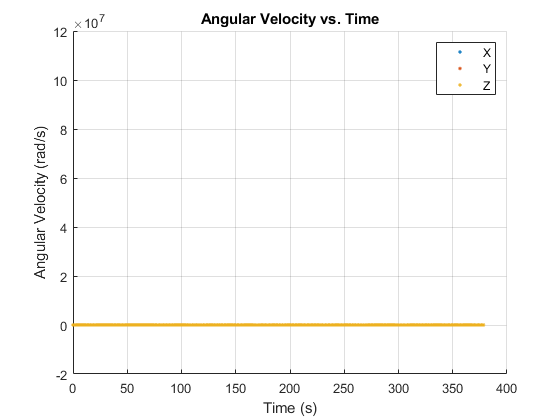

figure
hold on; grid on; scatter(t, [gyrox, gyroy, gyroz], '.'); title('Angular Velocity vs. Time');  
xlabel('Time (s)'); ylabel('Angular Velocity (rad/s)'); legend('X', 'Y', 'Z'); set(gcf,'Visible','on'); hold off;

orient_means = [mean(eulers(:,3)); mean(eulers(:,2)); mean(eulers(:,1))];        % XYZ
orient_meds = [median(eulers(:,3)); median(eulers(:,2)); median(eulers(:,1))];   % XYZ
orient_devs = [std(eulers(:,3)); std(eulers(:,2)); std(eulers(:,1))];
accel_means = [mean(accelx); mean(accely); mean(accelz)];
accel_meds = [median(accelx); median(accely); median(accelz)];
accel_devs = [std(accelx); std(accely); std(accelz)];
gyro_means = [mean(gyrox); mean(gyroy); mean(gyroz)];
gyro_meds = [median(gyrox); median(gyroy); median(gyroz)];
gyro_devs = [std(gyrox); std(gyroy); std(gyroz)];

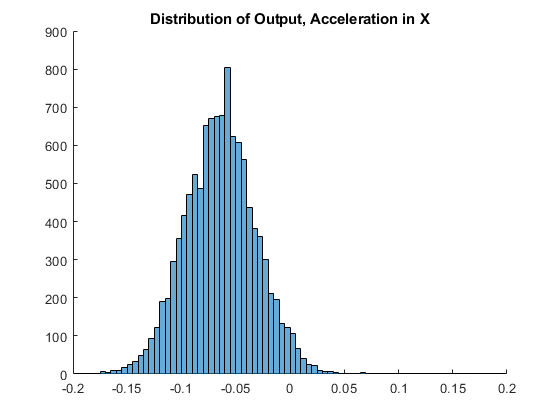

errorx = zeros(L,1);
for i = 1:L
    errorx(i) = abs(accelx(i) - accel_means(1));
end

figure
hold on; histogram(accelx); xlim([-.2, .2]); title('Distribution of Output, Acceleration in X'); set(gcf,'Visible','on'); hold off

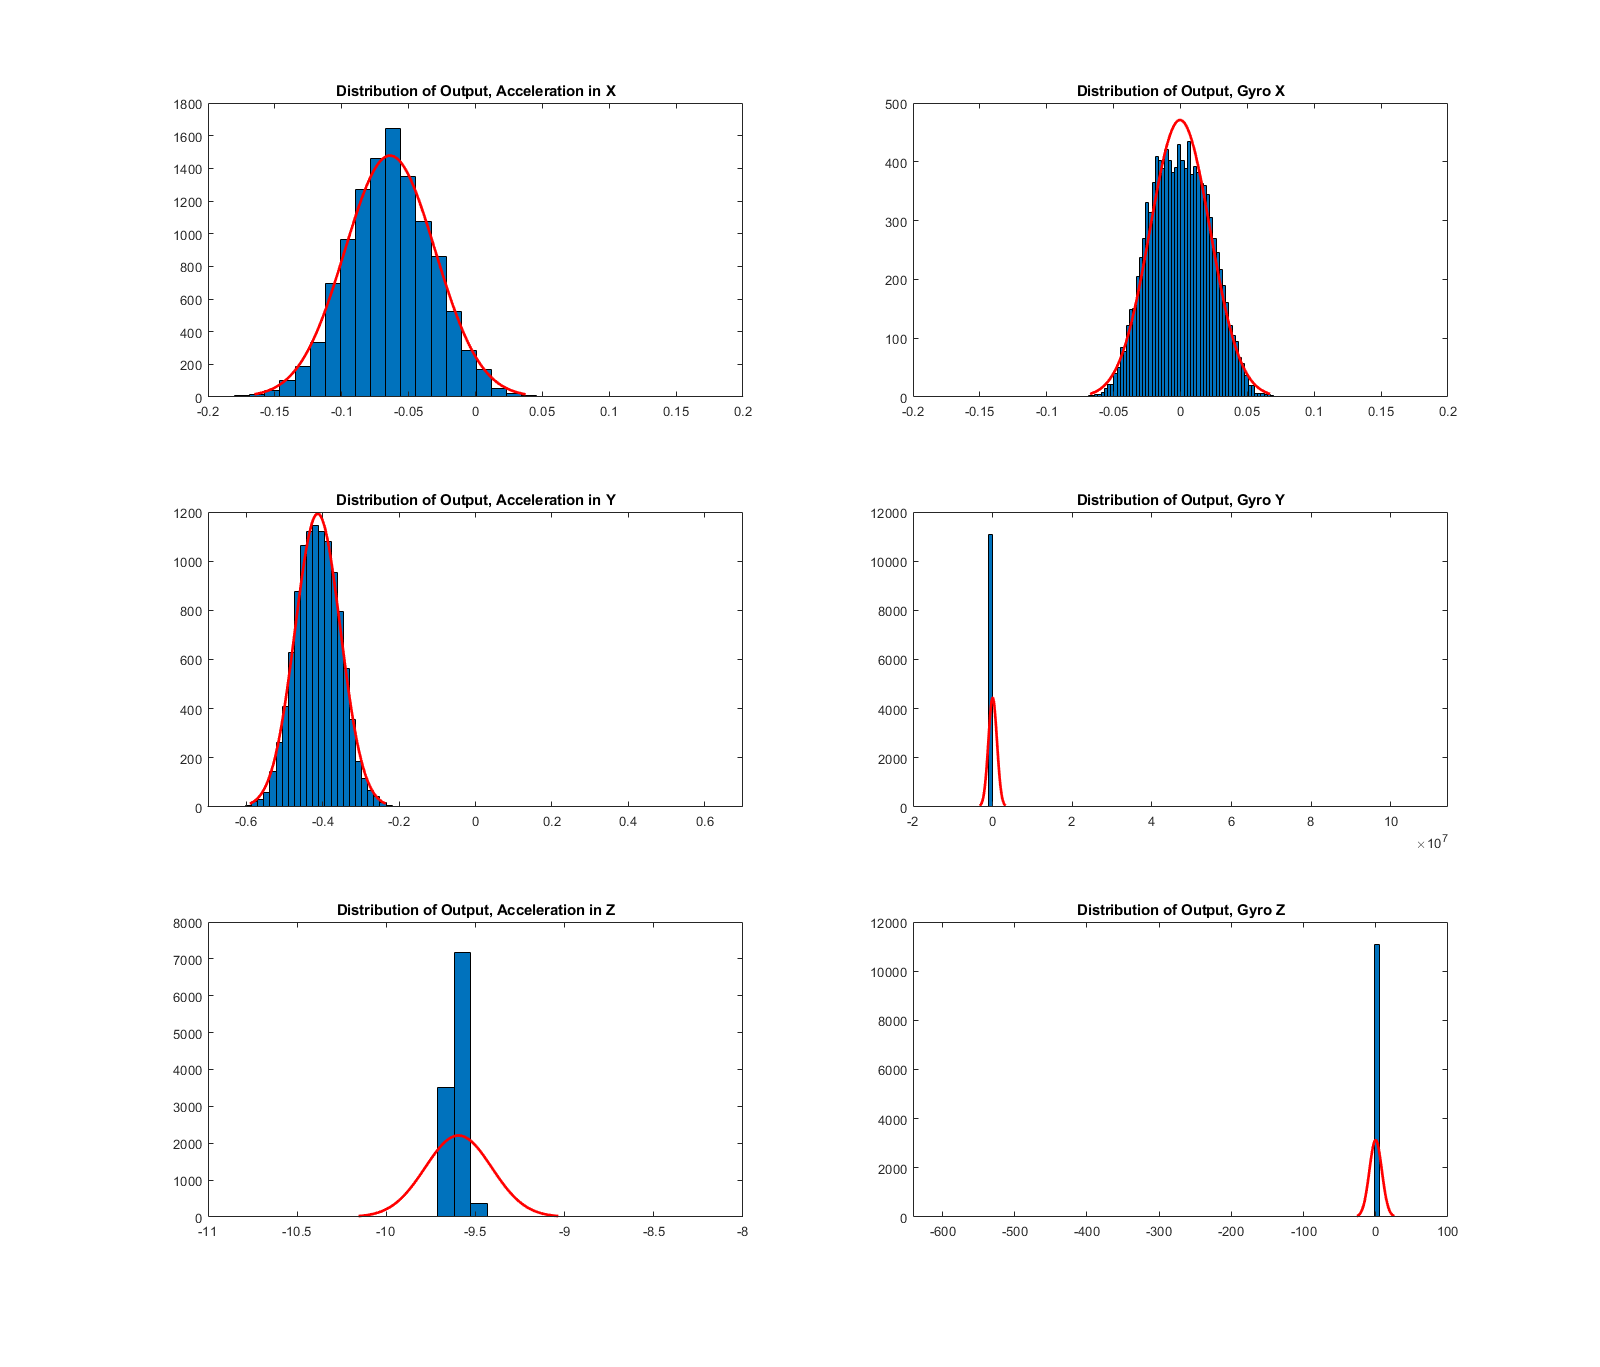


figure
set(gcf, 'position', [0 0 1600 2400]);
hold on; subplot(3,2,1); histfit(accelx); xlim([-.2, .2]); title('Distribution of Output, Acceleration in X'); 
subplot(3,2,3); histfit(accely); xlim([-.7, .7]); title('Distribution of Output, Acceleration in Y');
subplot(3,2,5); histfit(accelz); xlim([-11, -8]); title('Distribution of Output, Acceleration in Z'); 
subplot(3,2,2); histfit(gyrox); xlim([-.2, .2]); title('Distribution of Output, Gyro X'); 
subplot(3,2,4); histfit(gyroy); title('Distribution of Output, Gyro Y'); 
subplot(3,2,6); histfit(gyroz); title('Distribution of Output, Gyro Z'); set(gcf,'Visible','on'); hold off;

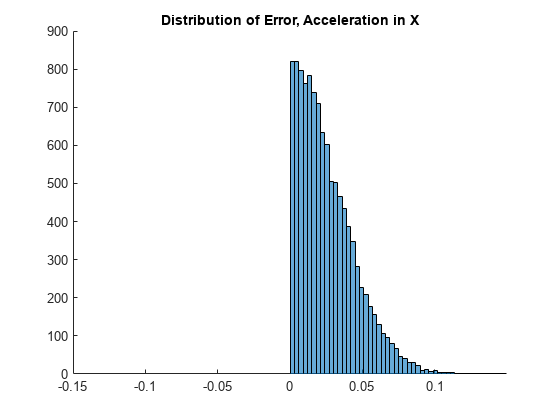


figure
hold on; histogram(errorx); xlim([-.15, .15]); title('Distribution of Error, Acceleration in X'); hold off;

pdaccelx = fitdist(accelx, 'normal')

pdaccelx =   NormalDistribution

  Normal distribution
       mu = -0.0639237   [-0.064553, -0.0632944]
    sigma =  0.0337995   [0.0333604, 0.0342504]


pdaccely = fitdist(accely, 'normal')

pdaccely =   NormalDistribution

  Normal distribution
       mu = -0.412782   [-0.413886, -0.411678]
    sigma = 0.0592991   [0.0585287, 0.0600902]


pdaccelz = fitdist(accelz, 'normal')

pdaccelz =   NormalDistribution

  Normal distribution
       mu = -9.59561   [-9.59909, -9.59214]
    sigma = 0.186817   [0.18439, 0.18931]



pdgyrox = fitdist(gyrox, 'normal')

pdgyrox =   NormalDistribution

  Normal distribution
       mu = -0.000338517   [-0.000756121, 7.90876e-05]
    sigma =    0.0224304   [0.022139, 0.0227296]


pdgyroy = fitdist(gyroy, 'normal')

pdgyroy =   NormalDistribution

  Normal distribution
       mu =     10214.6   [-9809.89, 30239.1]
    sigma = 1.07556e+06   [1.06158e+06, 1.08991e+06]


pdgyroz = fitdist(gyroz, 'normal')

pdgyroz =   NormalDistribution

  Normal distribution
       mu = -0.219677   [-0.380259, -0.0590956]
    sigma =   8.62519   [8.51314, 8.74026]
